# Create Terrain-Aware Global Planners for Offroad Navigation

In the [previous example](matlab:open('./CreateRoutePlannerUsingDigitalElevationData.mlx')), a graph-based planner was developed to plan routes through a road network derived from the offroad elevation data of a copper mine. In this section, you will develop a simple onramp planner to help connect the vehicle to the shortest path through the road-network. Later, you will provide [`plannerHybridAStar`](https://www.mathworks.com/help/nav/ref/plannerhybridastar.html) with a custom cost function that allows for terrain-aware planning. This planner can be used in regions of the map that lack structure, or as a fallback planner in the event that the path-following controller fails to find a local solution.

## Load Path Information from Image Procession Pipeline

Begin with the image and path-list results produced towards the end of the terrain processing example. For this example, you can load data generated during a previous run of the first example, or if you decided to save your own results, you can use those here instead.

load("OpenPitMinePart1Data.mat","imSlope","pathList","dem");

In the previous example, you identified the "roads" through the terrain using image processing techniques and a few example helpers. These paths were stored as a struct-array containing Nx2 sequences of IJ indices. Reality might be a simulation, but it still tends to be mapped in cartesian or geodesic coordinates, so let's convert these roads to XY using an occupancy-map populated with the slope-mask of the terrain, `imSlope`.

% Create map with resolution of 1 cell per meter
res = 1;
binMap = binaryOccupancyMap(~imSlope,res);

% Convert the grid-based paths to local XY coordinates
localPathList = pathList;
for i = 1:numel(pathList)
    localPathList(i).Path = grid2local(binMap,pathList(i).Path);
end

## Plan Path Using A*

Similar to the previous example, convert the list of XY paths to a `navGraph` and place this inside [`plannerAStar`](https://www.mathworks.com/help/nav/ref/plannerastar.html). This will serve as a high-level planner that generates pre-computed routes through the mine. For this example, the `maxEdgeSize` is set to 50. This should improve the likelihood that any `start` and `goal` SE2 poses will have a collision-free path to the nearest node's edges, while keeping the graph relatively sparse.

% Convert raw path list to graph information
maxElementPerEdge = 50;
[nodes,edges,edge2pathIdx,cachedPaths] = exampleHelperPath2GraphData(localPathList,maxElementPerEdge);

% Compute edge weights
edgeCosts = exampleHelperDefaultEdgeCost(cachedPaths,edge2pathIdx);

% Create A* planner using the navGraph
stateTable = table(nodes,VariableNames={'StateVector'});
linkTable = table(edges,edgeCosts,edge2pathIdx(:),VariableNames={'EndStates','Weight','Edge2PathIdx'});
roadNetwork = navGraph(stateTable,linkTable);
routePlanner = plannerAStar(roadNetwork);

Next plan a path through the graph, with start and goal poses lying away from the graph. Note that these poses contain orientation, which will become relevant in the later sections, but the graph only considers XY.

% Make start location slightly off the graph
start = [286.5 423.5 -pi/2];
goal  = [795.5 430.5  pi];

% Find closest node to start and goal location
[dStart,nearStartIdx] = min(vecnorm(nodes(:,1:2)-start(1:2),2,2));
[dGoal,nearGoalIdx] = min(vecnorm(nodes(:,1:2)-goal(1:2),2,2));

% Plan a route using just the graph
[waypoints, solnInfo] = plan(routePlanner,nearStartIdx,nearGoalIdx);

Once a path is found, use the `Edge2PathIdx` metadata stored on the `edges` of your [`navGraph`](https://www.mathworks.com/help/nav/ref/navgraph.html) to reconstruct the full path from `cachedPaths:`

% Convert path to link-sequence
edgePairs = [solnInfo.PathStateIDs(1:end-1)' solnInfo.PathStateIDs(2:end)'];
linkID = findlink(routePlanner.Graph,edgePairs);
networkPath = vertcat(cachedPaths(routePlanner.Graph.Links.Edge2PathIdx(linkID)).Path);

Downstream controllers often benefit from smooth reference paths if the vehicle has non-holonomic constraints. There are many ways to smooth a path via curve fitting or interpolation, here the [`exampleHelperSmoothPath`](matlab:open('exampleHelperSmoothPath')) helper subsamples the incoming path, fits a piece-wise continuous cubic polynomial to the remaining points and then resamples the path and orientation. A larger `subsampleInterval` should result in a smoother path but can also allow for a greater deviation between original and resampled paths. 

subsampleInterval = 5;
smoothedNetworkPath = exampleHelperSmoothPath(networkPath,subsampleInterval);

### Visualize Road Network and Path found Using plannerAStar

hIm = show(binMap);
hold on

gHandle = show(routePlanner.Graph); 
gHandle.XData = routePlanner.Graph.States.StateVector(:,1); 
gHandle.YData = routePlanner.Graph.States.StateVector(:,2);
exampleHelperPlotLines(networkPath,{"LineWidth",3});
exampleHelperPose2Quiver(smoothedNetworkPath,{"AutoScale","off"});
scatter(start(1),start(2),"o","filled");
scatter(goal(1),goal(2),"o","filled");
legendStrings = ["navGraph","graphRoute","smoothedPath","Start","Goal"]

legendStrings = 1×5 string array
    "navGraph"    "graphRoute"    "smoothedPath"    "Start"    "Goal"


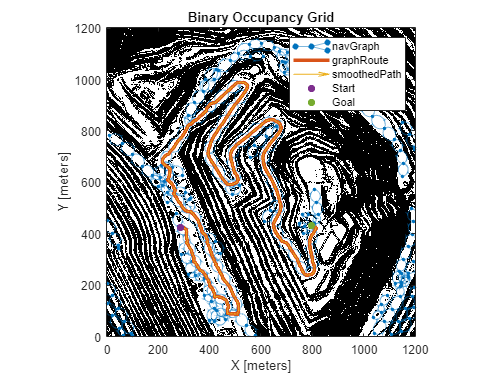

legend(legendStrings);

# Develop Onramp Planner

The `networkPath` generated by the route planner in the previous section only represents the shortest path *inside *the network, so the next step is to connect the `start` location to the route. 

First look up all nodes that are connected to the start node using the graph's [`successors`](https://www.mathworks.com/help/nav/ref/navgraph.successors.html) function:

successorNodeIDs = successors(routePlanner.Graph,solnInfo.PathStateIDs(1));

next use the graph's [`findlink`](https://www.mathworks.com/help/nav/ref/navgraph.findlink.html) function to retrieve the IDs of the links connecting the initial node to its successors:

initLinkNodePair = [repmat(solnInfo.PathStateIDs(1),numel(successorNodeIDs),1) successorNodeIDs(:)];
initLinkID = findlink(routePlanner.Graph,initLinkNodePair);

and lastly retrieve the full paths for each edge by indexing into the `cachedPaths` using the `Edge2PathIdx` meta-data stored in `links`.

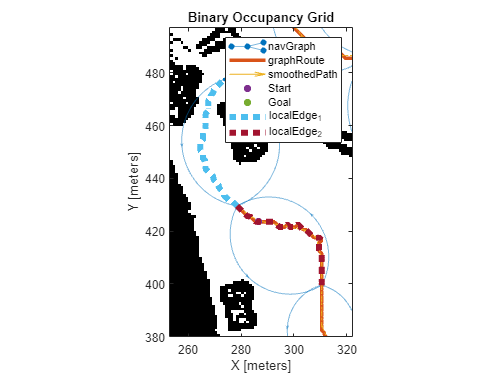

initEdgePaths = cachedPaths(routePlanner.Graph.Links.Edge2PathIdx(initLinkID));

% Display local neighbor paths to initial node in the solution
for i = 1:numel(initEdgePaths)
    if ~isequal(initEdgePaths(i).Path(1,:),networkPath(1,:))
        initEdgePaths(i).Path = flipud(initEdgePaths(i).Path);
    end
    exampleHelperPlotLines(initEdgePaths(i).Path,{":","LineWidth",5});
end
exampleHelperPaddedZoom(initEdgePaths,2,DataGetter=@(x)x.Path,PaddingFactor=1.5);
legend([legendStrings(:); "localEdge_" + (1:numel(initEdgePaths))']);

Next, use the helper [`exampleHelperConnectRSToPath`](matlab:open('exampleHelperConnectRSToPath')) to find a collision-free connection between the `start` pose and `networkPath`. The helper works by attempting to connect a Reeds-Shepp segment between the initial pose and the edges connected to the start-node. These connections are attempted from the nearest to farthest points and exits when a collision-free segment is found, or all points have been exhausted.

% Define the min turn radius of the vehicle
minTurnRadius = 17.2; % Default turn radius for a large mine vehicle

% Find closest obstacle-free path between start state and planned route
onrampPath = exampleHelperConnectRSToPath(smoothedNetworkPath, initEdgePaths, start, binMap, minTurnRadius);

The final step is to combine the two path segments.

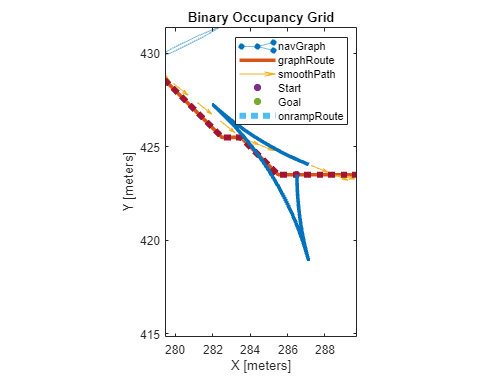

origStates = [onrampPath; smoothedNetworkPath];

% Display the nearest path and closest neighbor
exampleHelperPlotLines(onrampPath,{"LineWidth",3});
exampleHelperPaddedZoom(onrampPath,2,PaddingFactor=2);
legend({"navGraph","graphRoute","smoothPath","Start","Goal","onrampRoute"});

# Develop Terrain-Aware Planner

In the previous sections you developed tools for creating and planning on road networks where none originally existed, but what should be done if there is no clear way to reach this network, or if the vehicle is in a region where a road network cannot be inferred? In this section you will learn how to make `plannerHybridAStar` "terrain-aware" by supplying a custom cost function. 

## Define Parameters of Vehicle and Global Planner

Begin by specifying some parameters needed to represent the geometry and kinematic constraints of the vehicle. These have been roughly separated into a set of parameters that might change throughout the vehicle's operation, like costs, and those that will likely remain fixed, like the length and width of the vehicle:

% Get params for free-space planner
[tuneableTerrainAwareParams, fixedTerrainAwareParams] = exampleHelperTerrainPlannerParams

tuneableTerrainAwareParams = struct with fields:
          MinTurningRadius: 17.2000
     MotionPrimitiveLength: 22.5147
               ForwardCost: 1
               ReverseCost: 1
    DirectionSwitchingCost: 1
                  MaxAngle: 15


fixedTerrainAwareParams = struct with fields:
                       Length: 6.5000
                        Width: 5.7600
          NumMotionPrimitives: 5
    AnalyticExpansionInterval: 3
        InterpolationDistance: 1
                   NumCircles: 3
                   Resolution: 1


Next, convert the digital elevation model generated in the previous example to a cost map containing gradient and cost information:

% Create costMaps from dem
[costMap,maxSlope] = exampleHelperDem2mapLayers(dem,tuneableTerrainAwareParams.MaxAngle,fixedTerrainAwareParams.Resolution);
obstacles = getLayer(costMap,"terrainObstacles");

For the sake of this example, let's ensure there is enough room around the previously-computed road network to allow the global planners to operate. To do this, convert the road-network to an occupancy map, inflate it by a desired radius, and then remove those inflated cells from the slope mask. Note that in the real world, you may instead want to remove roads that are too narrow to traverse.

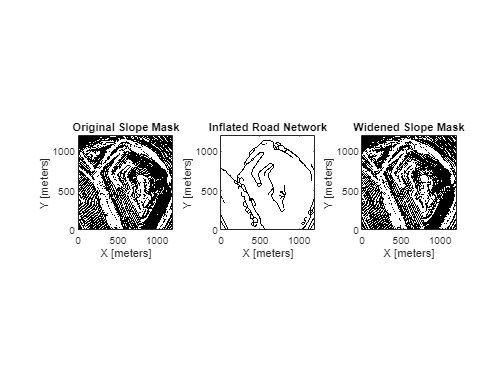

% Create an empty map of equal size to current obstacle map
tmpMap = binaryOccupancyMap(zeros(obstacles.GridSize),Resolution=obstacles.Resolution);

figure;
subplot(1,3,1);
show(obstacles);
title('Original Slope Mask');
% Inflate the roadnetwork
vehDims = exampleHelperVehicleGeometry(fixedTerrainAwareParams.Length,fixedTerrainAwareParams.Width,"collisionChecker");
collisionChecker = inflationCollisionChecker(vehDims,fixedTerrainAwareParams.NumCircles);
setOccupancy(tmpMap,vertcat(pathList.Path),1,'grid');
inflate(tmpMap,collisionChecker.InflationRadius*1.5);

subplot(1,3,2);
show(tmpMap);
title('Inflated Road Network');

% Remove inflated skeleton from the original map
setOccupancy(obstacles,obstacles.occupancyMatrix & ~tmpMap.occupancyMatrix);

subplot(1,3,3);
show(obstacles);
title('Widened Slope Mask');

## Create `plannerHybridStar` Object with Custom Cost Function

The example helper [`exampleHelperCreateTerrainPlanner`](matlab:open('exampleHelperCreateTerrainPlanner')) initializes `plannerHybridAStar` with the previously created `costMap` and parameters. 

terrainPlanner = exampleHelperCreateTerrainPlanner(costMap,tuneableTerrainAwareParams,fixedTerrainAwareParams);

By default the helper populates the planner's `TransitionCostFcn` with [`exampleHelperZHeuristic`](matlab:open('exampleHelperZHeuristic'))`:`

This helper adds the change in terrain height to the distance along the motion-primitive, but any function which supports the `TransitionCostFcn` interface can be supplied as an optional fourth input. See the following for more details:

## Plan Terrain-Aware Path

Next you will set the end of the path generated from the `routePlanner` as the `start` of the terrain-aware problem and plan a path to the `goal` location that lies off the road network.

start = origStates(end,:); 

% Plan route
[terrainAwarePath,motionDir,solnInfo] = plan(terrainPlanner,start,goal);

% Save the robot states by concatenating the terrain aware results from the end of the path.
networkPoses = [networkPath headingFromXY(networkPath)];
originalReferencePath = [onrampPath; networkPoses; terrainAwarePath.States];
smoothedReferencePath = [origStates; terrainAwarePath.States];

## Visualize Path from Terrain-Aware Planner

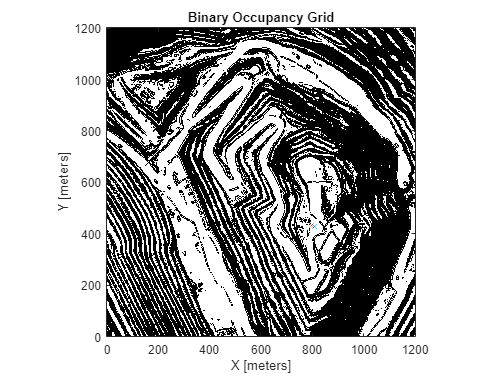

% Display map, start, and goal
obstacles = getLayer(costMap,"terrainObstacles");
figure;
h = show(obstacles);
hold on;
exampleHelperPlotLines(start,"X");
exampleHelperPlotLines(goal,"X");

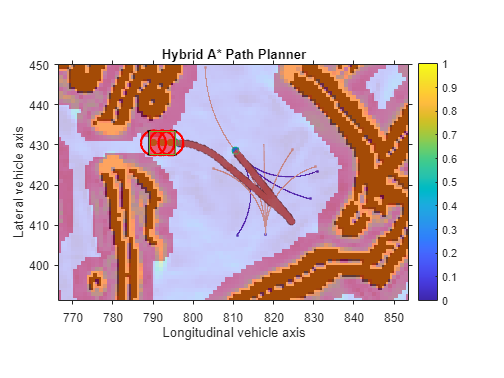

% Display planner results
figure
show(terrainPlanner);
hold on;
exampleHelperVisualizeTerrainPlanner(terrainAwarePath.States,costMap,fixedTerrainAwareParams,tuneableTerrainAwareParams);

## Conclusion

In this example you developed two different ways of generating collision-free paths while satisfying the vehicle's kinematic and geometric constraints. 

The first half of the example focused on generating collision-free paths between a vehicle's SE2 location and a route found in the road network. You used the [`reedsSheppConnection`](https://www.mathworks.com/help/nav/ref/reedssheppconnection.html) supplied with the vehicle's `MinTurningRadius` to generate potential connections to the network, and used a [`validatorVehicleCostmap`](https://www.mathworks.com/help/nav/ref/validatorvehiclecostmap.html) supplied with the vehicle's dimensions to check whether those paths were collision-free.

The second half of the example focused on supplying `plannerHybridAStar` with a custom cost function that added elevation to the transition cost, biasing the planner towards solutions that minimize vertical motion. This planner also received the same `MinTurningRadius` and `validatorVehicleCostmap`, and can be used in scenarios where the simple onramp planner fails to find a connection or in regions of the map where the road-network does not exist.

In the [next example](matlab:open('./CreateLocalPlannerToNavigateGlobalPath.mlx')) you will use [`controllerTEB`](https://www.mathworks.com/help/nav/ref/controllerteb.html) as a local-planner capable of following the global paths generated here while avoiding obstacles and adhering to the same kinematic and geometric constraints.

*Copyright 2023 The MathWorks, Inc.*